imgs_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


labels_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


ans =          512         512           3        1486


ans =          512         512           3        1486


accur =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


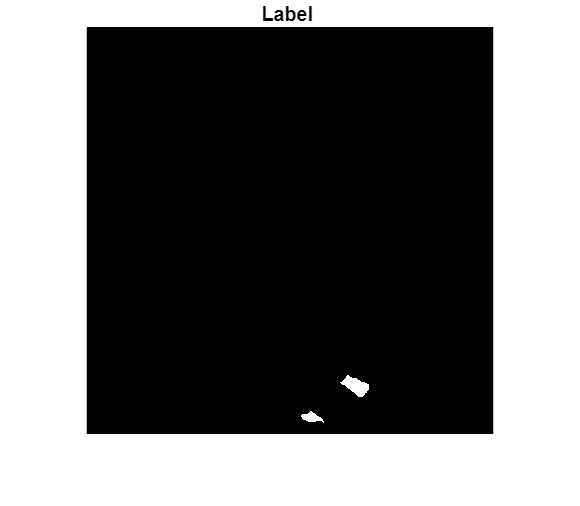

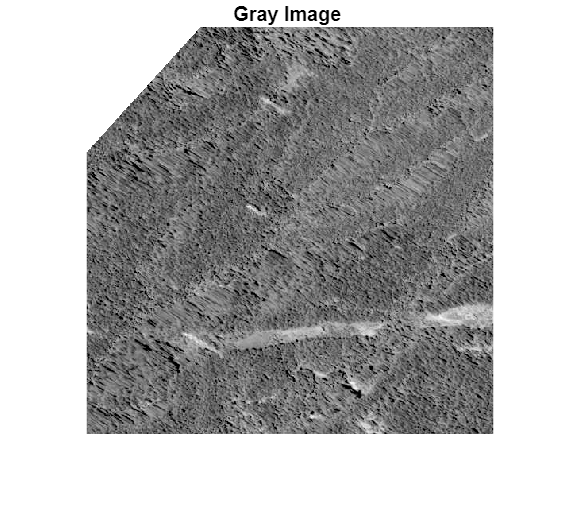

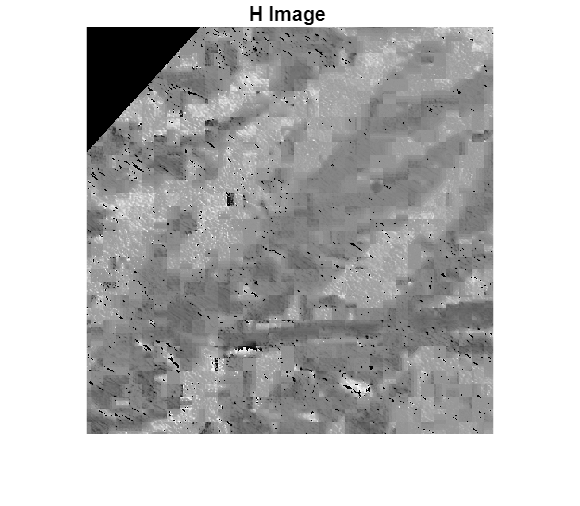

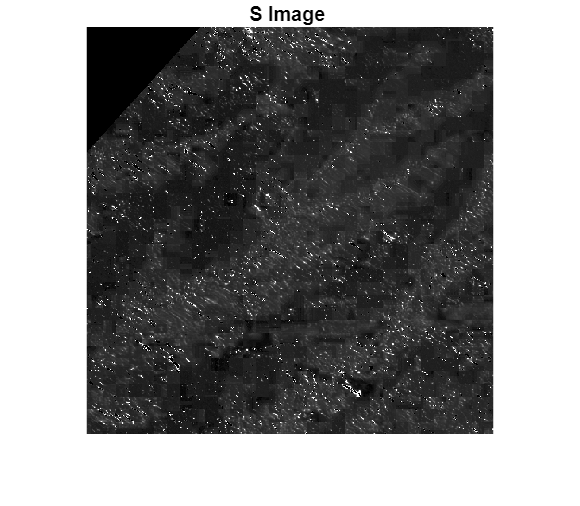

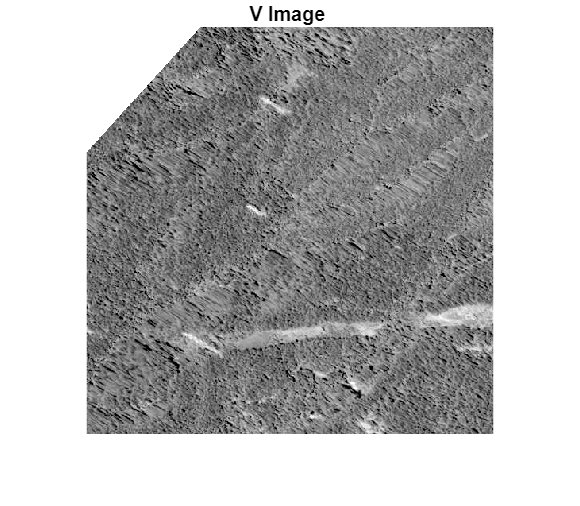

mask_landslide =     0.7362    1.3645    0.8150    0.8099


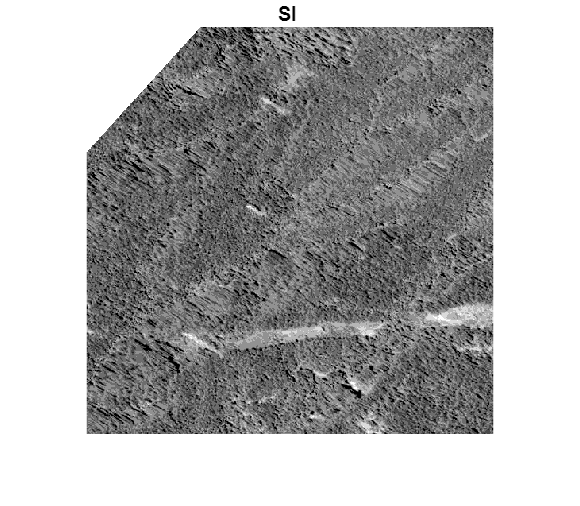

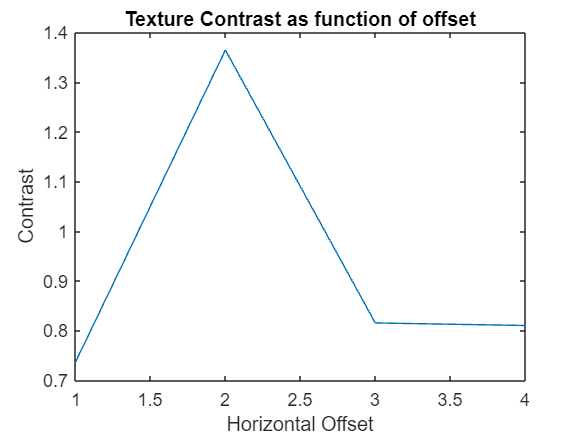

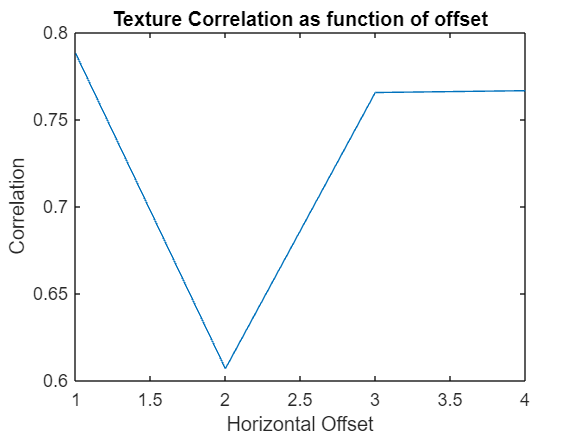

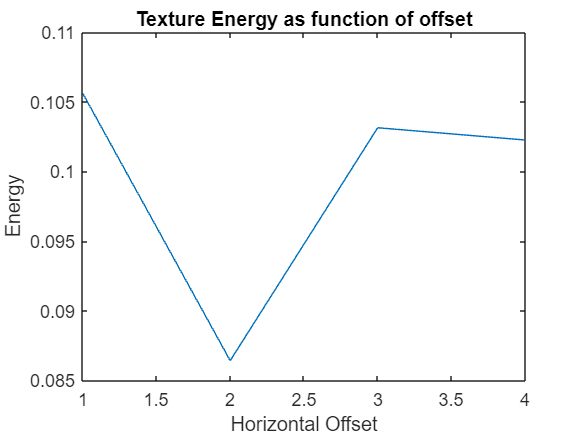

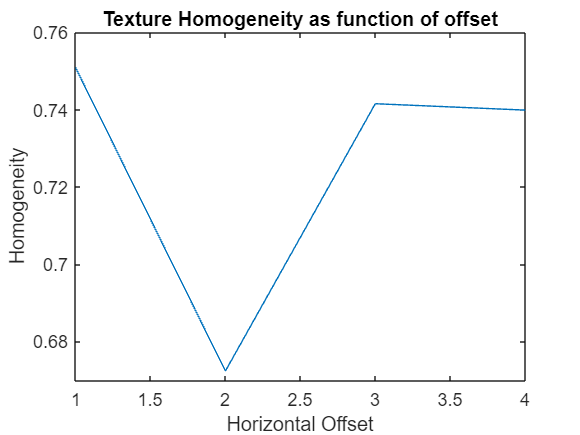

clear all
% Setup
dataset_directory = "C:\Users\andre\Year5\EE581\Project\Datasets\Full_CAS\Hokkaido Iburi-Tobu";
img_directory = dataset_directory + "\img\";
label_directory = dataset_directory + "\label\";
mask_directory = dataset_directory + "\mask\";

% Store all images and labels
imgs_files=dir(img_directory)
labels_files=dir(label_directory)
imgs = zeros(512,512,3,length(imgs_files),'uint8');
labels = zeros(512,512,3,length(imgs_files),'uint8');
for i=1:length(imgs_files)
    if imgs_files(i).name(1) == 'H'
        imgs(:,:,:,i-2) = double(imread(img_directory + imgs_files(i).name));
    end
    if labels_files(i).name(1) == 'H'
        labels(:,:,:,i-2) = double(imread(label_directory + labels_files(i).name));
    end
end
size(imgs)
size(labels)

t1 = datetime('now');
accur = zeros(1,size(imgs,4))
for i=1%:size(imgs,4)
    % Read image
    img = imgs(:,:,:,i);
    label = labels(:,:,:,i);
    label_= label;
    label_(label_ == 255) = 1;
    label_bin = (label_(:,:,1) + label_(:,:,2) + label_(:,:,3)) > 0;
    label = 1 - label_bin;    
    img_gray = rgb2gray(img);
    img_hsv = rgb2hsv(img);
    
    % Determine what provides most promininent landlside features
    figure;
    imshow(label);
    title('Label ',i);
    figure;
    imshow(img_gray);
    title('Gray Image ',i);
    figure;
    imshow(img_hsv(:,:,1));
    title('H Image ',i);
    figure;
    imshow(img_hsv(:,:,2));
    title('S Image ',i);
    figure;
    imshow(img_hsv(:,:,3));
    title('V Image ',i);

    offsets = [0 1; -1 1; -1 0; -1 -1]; % Different directions
    [glcm, SI] = graycomatrix(img_gray, Offset=offsets); %, Symmetric=true);
    stats = graycoprops(glcm, {'Contrast', 'Correlation', 'Energy', 'Homogeneity'}); 
    % High contrast is rough terrain (landlside)
    % Low E is more randomness (lanslide distrutpins)
    % High homogeneirty is uniform areas (vegetation or stable land)

    mask_landslide = stats.Contrast

    figure;
    imshow(rescale(SI));
    title('SI ',i);

    figure, plot([stats.Contrast]);
    title('Texture Contrast as function of offset');
    xlabel('Horizontal Offset');
    ylabel('Contrast');
    figure, plot([stats.Correlation]);
    title('Texture Correlation as function of offset');
    xlabel('Horizontal Offset');
    ylabel('Correlation');
    figure, plot([stats.Energy]);
    title('Texture Energy as function of offset');
    xlabel('Horizontal Offset');
    ylabel('Energy');
    figure, plot([stats.Homogeneity]);
    title('Texture Homogeneity as function of offset');
    xlabel('Horizontal Offset');
    ylabel('Homogeneity');
end